if ~exist('data/chap10', 'dir')
    gunzip('https://ss-takashi.sakura.ne.jp/corpus/jvnv/jvnv_ver1.zip','data')
    unzip('data/jvnv_ver1.zip', 'data/chap10/')
end

プログラム 10.2

[yA, sr] = audioread('data/chap10/jvnv_v1/M2/sad/regular/M2_sad_regular_43.wav');

VAD_THRESHOLD_RMS = 0.01;
FRAME_LENGTH = floor(0.1*sr);
FRAME_SHIFT = 256;
FRAME_SHIFT_SEC = FRAME_SHIFT / sr;
SILENCE_THRESHOLD_FRAMES = 10;

vad = calculate_vad(yA,VAD_THRESHOLD_RMS,FRAME_LENGTH,FRAME_SHIFT);

プログラム 10.3

[silence_beg, silence_end] = identify_silence(vad, SILENCE_THRESHOLD_FRAMES);
[ipu_beg_sec, ipu_end_sec] = compute_speech_intervals(silence_beg, silence_end, ...
    SILENCE_THRESHOLD_FRAMES, FRAME_SHIFT_SEC);

[ipu_beg_ms, ipu_end_ms] = compute_speech_intervals(silence_beg, silence_end, ...
    SILENCE_THRESHOLD_FRAMES, FRAME_SHIFT)

ipu_beg_ms =            0       42752      151040      242944      258560


ipu_end_ms =        28672       90624      189952      246272      300032


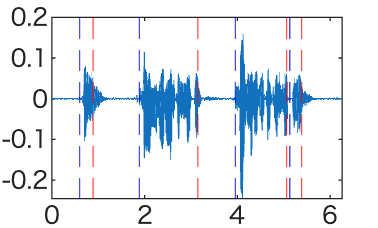

t = (0:(length(yA)-1))/sr;
plot(t,yA); hold on
xline(ipu_beg_sec(2:end), 'LineStyle','--','Color','r')
xline(ipu_end_sec(1:end-1), 'LineStyle','--','Color','b'); hold off

プログラム 10.4

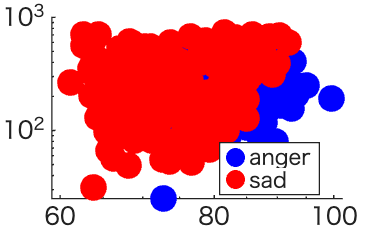

jvnv_path = 'data/chap10/jvnv_v1/';
speaker_list = ["F1","F2","M1","M2"];
emotion_list = ["anger", "sad"];

speaker = []; emotion = []; feat1 = []; feat2 = [];
for sidx = 1:length(speaker_list)
    for eidx = 1:length(emotion_list)
        wav_dir = [jvnv_path, char(speaker_list(sidx)), '/', ...
            char(emotion_list(eidx)), '/regular/'];
        nv_label_dir = [jvnv_path, 'nv_label/', char(speaker_list(sidx)), '/'];
        files = dir([wav_dir, '*.wav']);
        for file_idx = 1:length(files)
            f = files(file_idx).name;
            [path,name,ext] = fileparts(f);
            nv_label_file = [nv_label_dir,'/',name,'.txt'];
            [nv_beg,nv_end] = getNvTime(nv_label_file);
            [wav_data, sr] = audioread([files(file_idx).folder,'/',f]);
            wav_data_nv = wav_data(round(nv_beg*sr):round(nv_end*sr));
            [intensity, fo_range] = getAcousticFeature(wav_data_nv, sr);

            speaker = [speaker speaker_list(sidx)];
            emotion = [emotion emotion_list(eidx)];
            feat1 = [feat1 intensity];
            feat2 = [feat2 fo_range];
        end
    end
end

column_name = ["Emotion" "Intensity" "Fo_Range"];
tbl = table(emotion', feat1', feat2', VariableNames=column_name);
gscatter(tbl.Intensity, tbl.Fo_Range, tbl.Emotion,"br",'.',30);
set(gca, 'XScale', 'log', 'YScale', 'log')

function vad = calculate_vad(y, threshold, frame_length, frame_shift)
N = floor(length(y)/frame_shift);
y((N-1)*frame_shift+frame_length+1)=0;
Frame = y(repmat(1:frame_length,N,1)+repmat((0:(N-1))'*frame_shift,1,frame_length))';
vad = sqrt(mean(Frame.^2,1))>threshold;
end

function [silence_beg, silence_end] = identify_silence(vad, silence_threshold_frames)
silence_beg = [1 find(diff(vad)==-1)+1];
silence_end = [find(diff(vad)==1)+1 length(vad)];
end

function [ipu_beg_ms, ipu_end_ms] = compute_speech_intervals( ...
    silence_beg, silence_end, silence_threshold_frames, FRAME_SHFT_SEC)
    valid = silence_end-silence_beg > silence_threshold_frames;
    ipu_beg_ms = (silence_beg(valid)-1)*FRAME_SHFT_SEC;
    ipu_end_ms = (silence_end(valid)-1)*FRAME_SHFT_SEC;
end

function [nv_beg, nv_end] = getNvTime(nv_label_file)
tbl = readtable(nv_label_file);
nv_beg = tbl.Var1;
nv_end = tbl.Var2;
end

function [intensity, fo_range] = getAcousticFeature(wav_data_nv, fs)
squared_wav_data_nv = wav_data_nv.^2;
rms = sqrt(mean(squared_wav_data_nv));
pitch_floor = 75;
effective_window_length = int32(3.2/pitch_floor*fs);
kaiser_window = kaiser(effective_window_length,20);
intensity_wave = conv(squared_wav_data_nv, kaiser_window, 'same');
reference_pressure = 20e-6;
intensity_dB = 10*log10(intensity_wave/ ...
    reference_pressure^2 + 1e-10);
intensity = mean(intensity_dB);
fo = Harvest(wav_data_nv, fs);
fo = fo.f0;
fo = fo(fo~=0);
if isempty(fo)
    fo_range = 0;
else
    fo_range = range(fo);
end
end